# Computational Analysis of RNA Polymerase Ribozyme Activity and Phylogeny

## Data Loading

Polymerase ribozyme data was obtained from Tjhung *et al.* 2020 in GEO database entry [GSE142114](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE142114). Sequences were obtained from [Appendix, Table S4](https://www.pnas.org/content/pnas/suppl/2020/01/21/1914282117.DCSupplemental/pnas.1914282117.sapp.pdf) of the same study.

In the raw sequencing data, 1739398 reads were obtained for sequencing of Pol 24-3 transcripts. 162136 reads were obtained from sequencing of Pol 38-6 transcripts.

% Sequences
pol24_3 = ['AGUCAUUGCCGCACGAAAGACAAAUCUGCCCUCAGAGCUUGAGAACAUCUUCGGAUGC' ...
    'AGAGGAGGCAGCCUUCGGUGGAACGAUCGUGCCACCGUUCUCAACACGUACCCGAACGAAAAAGA' ...
    'CCUGACAAAAAGGCGUUGUUAGACACGCCCAGGUGCCAUACCCAACACAUGGCUGAC'];

pol38_6 = ['AGUCAUUGCCGCACAAAGACAAAUCUCCCCUCAGAGCUUGAGAACAUCUACGGAUGCAG' ...
    'AGGAGGGGGCCUUCGGUGGAUCAAUUGUGCACCACCGUUCUCAACACGUACCCGAACAUAAAAAGA' ...
    'CCUGACAAAAAGGCGAUGUUAGACACGCACAGGUGCCAUACCCAACACAUGGCUGAC'];

ligase = ['GGAAAAGACAAAUCUGCCCUCAGAGCUUGAGAACAUCUUCGGAUGCAGGGGAGGCAGCC' ...
    'CCCGGUGGCUUUAACGCCAACGUUCUCAACAAUAGUGA'];

hammerhead = 'CACUCCACACGACGUACUGAUGAGGCCGAAAGGCCGAAAAGCG';


% Polymerase transcript RNA seq read data
data24_3 = readtable("GSE142114_NGS_Hammerhead_Length_Filtered.xlsx",'Sheet','24-3 raw data');


data38_6 = readtable("GSE142114_NGS_Hammerhead_Length_Filtered.xlsx",'Sheet','38-6 raw data');

## Polymerase Processivity

Examining processivity of 38-6 and 24-3 ribozymes, where processivity is defined as the number of nucleotides the polymerase can add before terminating polymerization.

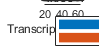

% Processivity data obtained using the processivity.m function:
[proc24_3,lengths_24] = processivity(data24_3);
[proc38_6,lengths_38] = processivity(data38_6);

% Add "Zero read" fields to 38-6 table
proc_38ends = proc24_3(end-3:end,:);
proc_38ends.Length = zeros(4,1);
proc38_6 = vertcat(proc38_6,proc_38ends);

% Combine to one table
proc24_3.Properties.VariableNames = {'Pol_24-3','Sequence'};
proc38_6.Properties.VariableNames = {'Pol_38-6','Sequence'};
proc_all = horzcat(proc38_6(:,1),proc24_3);

% Plot Processivity over sequence length and sequence identity:
seqlength = lengths_24;
sequencefull = proc_all.Sequence{end};
seq = dna2rna(sequencefull(seqlength));

% % Bar plot format (line plot format available in Proc_LinePlot.m)

figure; hold on;
    % Plot over transcript length
t = tiledlayout(1,1);
ax1 = axes(t);
bar(ax1,seqlength, [proc_all.("Pol_24-3") proc_all.("Pol_38-6")] ...
    ,'EdgeColor','none');
xlim([19,63])
xlabel('Transcript Length (nt)')
ax2 = axes(t);

    % plot over sequence
bar(ax2,seqlength, [proc_all.("Pol_24-3") proc_all.("Pol_38-6")] ...
    ,'EdgeColor','none');
ax2.Color = 'none';
ax2.XAxisLocation = 'top';
xlabel('Terminal Nucleotide')
xlim([19,63])
xticks(seqlength)
xticklabels(seq')

    % Set y-axis and plot size.
ax1.YAxis.Exponent = 0;
ax2.YAxis.Exponent = 0;
ylabel('Fraction of Total Sequencing Reads')

legend('Pol 24-3', 'Pol 38-6','Location','northwest')
x0=10;
y0=10;
widthx=3000;
heightx=2000;
set(gcf,'position',[x0,y0,widthx,heightx]);
saveas(gcf,'ProcessivityBar.png')
hold off;

## Polymerase Fidelity

Examining fidelity of 38-6 and 24-3 ribozymes, where fidelity is the ability of the polymerase to accurately copy the template when polymerizing the transcript. This is interrogated by examining mismatches, insertions, and deletions in the sequence.

First, we filter for the most enriched reads (read lengths accounting for >3% of all sequencing reads). This is done to prevent muddying of the data due to the normalization process (i.e. if there are insufficient reads to get an accurate estimation of errors).:

% Filtering using a 0.03 cutoff for fraction of total reads:

proc24_3x = addvars(proc24_3,seqlength,'Before',  'Pol_24-3');
proc24_3x = sortrows(proc24_3x,"Pol_24-3",'descend');
proc38_6x = addvars(proc38_6,seqlength,'Before', 'Pol_38-6');
proc38_6x = sortrows(proc38_6x,"Pol_38-6",'descend');
proc_allx = addvars(proc_all,seqlength,'Before',  'Pol_38-6');

filt24_3 = proc24_3x(proc24_3x.("Pol_24-3") > 0.03,1);
filt38_6 = proc38_6x(proc38_6x.("Pol_38-6") > 0.03,1);
filter = unique(vertcat(filt38_6,filt24_3)).seqlength;



Now, the filtered read data is processed to obtain error rate data. We first plot the transcript-length dependent data:

% Using the fidelity.m function:

[pos24_3,length24_3] = fidelity(data24_3,filter);
[pos38_6,length38_6] = fidelity(data38_6,filter);

mean24_3 = [mean(length24_3.ErrorRate) mean(pos24_3.ErrorRate)];
std24_3 = [std(length24_3.ErrorRate) std(pos24_3.ErrorRate)];
mean38_6 = [mean(length38_6.ErrorRate) mean(pos38_6.ErrorRate)];
std38_6 = [std(length38_6.ErrorRate) std(pos38_6.ErrorRate)];
lengths = length24_3.Length;
positions = pos24_3.Position;


 We first plot the transcript-length dependent data:

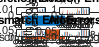

% Plot Length-Dependent Fidelity

figure; hold on;
subplot(2,2,1); % Deletions
bar([length24_3.Deletions,length38_6.Deletions] ...
    ,'EdgeColor','none');
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Deletions');
title('Deletion Errors')

legend('Pol 24-3', 'Pol 38-6','Location', 'northwest')


subplot(2,2,2); % Insertions
p = bar([length24_3.Insertions,length38_6.Insertions] ...
    ,'EdgeColor','none');
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Insertions'); ax = gca;
title('Insertion Errors')

subplot(2,2,3); % Mismatches
bar([length24_3.Mismatches,length38_6.Mismatches] ...
    ,'EdgeColor','none');
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Mismatches');
title('Mismatch Errors')

subplot(2,2,4); % ErrorRate
bar([length24_3.ErrorRate,length38_6.ErrorRate] ...
    ,'EdgeColor','none');
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Polymerization Error');
title('All Errors')

set(gcf,'position',[x0,y0,widthx,heightx]);
saveas(gcf,'LengthErrorBar.png')
hold off;

Next the position-dependent fidelity data is plotted:

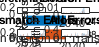


% Plot Position-Dependent Fidelity

figure; hold on;
subplot(2,2,1); % Deletions
bar(positions,[pos24_3.Deletions,pos38_6.Deletions] ...
    ,'EdgeColor','none');
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Deletions');
title('Deletion Errors');
legend('Pol 24-3', 'Pol 38-6','Location', 'northwest')


subplot(2,2,2); % Insertions
p = bar(positions,[pos24_3.Insertions,pos38_6.Insertions] ...
    ,'EdgeColor','none');
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Insertions'); ax = gca;
title('Insertion Errors')

subplot(2,2,3); % Mismatches
bar(positions,[pos24_3.Mismatches,pos38_6.Mismatches] ...
    ,'EdgeColor','none');
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Mismatches');
title('Mismatch Errors')

subplot(2,2,4); % ErrorRate
bar(positions,[pos24_3.ErrorRate,pos38_6.ErrorRate] ...
    ,'EdgeColor','none');
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Polymerization Error');
title('All Errors')

set(gcf,'position',[x0,y0,widthx,heightx]);
saveas(gcf,'PositionErrorBar.png')
hold off;

## Sequence Alignments

BLAST searches performed with Pol 38-6, Pol 24-3, and Class 1 ligase (polymerase ancestor) against nucleotide database to find homologous sequences.

% BLASTn search of Pol 38-6 and Pol 24-3 ribozymes against the nucleotide 
% collection database.
%% Remove comments on blastncbi() function calls to generate blast data.
[blast38_6,w1] = blastncbi(pol38_6,'blastn');
[blast24_3,w2] = blastncbi(pol24_3,'blastn');

bdat38_6 = getblast(blast38_6,'WaitTime',w1);

Blast results are not available yet. Please wait ...


bdat24_3 = getblast(blast24_3,'WaitTime',w1);

% BLASTn search of Class 1 Ligase ribozyme against the nucleotide collection
% database.
[blast_ligase,w3] = blastncbi(ligase,'blastn');

bdat_ligase = getblast(blast_ligase,'WaitTime',w3);


% % BLAST outputs are filtered for hits on genomic sequences (high nt
% length) using blastfilt.m function:

bfilt24_3 = blastfilt(bdat24_3);
bfilt38_6 = blastfilt(bdat38_6);
bfilt_ligase = blastfilt(bdat_ligase);

% Plot filtered BLAST outputs: show alignment length vs accession IDs of
% hits
figure;hold on;

bar(bfilt_ligase.AlignmentLength ...
    ,'EdgeColor','none');
xticks(1:length(bfilt_ligase.AlignmentLength))
xticklabels(bfilt_ligase.AccessionID)
xlabel('Accession ID'); ylabel('Alignment Length (nt)')
title('Class 1 Ligase BLAST')
saveas(gcf,'BlastLigase.png')
hold off;

figure;hold on;
subplot(1,2,1)
bar(bfilt24_3.AlignmentLength ...
    ,'EdgeColor','none');
xticks(1:length(bfilt24_3.AlignmentLength))
xticklabels(bfilt24_3.AccessionID)
xlabel('Accession ID'); ylabel('Alignment Length (nt)')
title('Pol 24-3 BLAST'); ylim([0 30])

subplot(1,2,2)
bar(bfilt38_6.AlignmentLength ...
    ,'EdgeColor','none');
xticks(1:length(bfilt38_6.AlignmentLength))
xticklabels(bfilt38_6.AccessionID)
xlabel('Accession ID'); ylabel('Alignment Length (nt)')
title('Pol 38-6 BLAST'); ylim([0 30])
saveas(gcf,'BlastPolys.png')
hold off;

Multiple Sequence Analysis of CP085530 with class 1 ligase, Pol 24-3, and Pol 38-6:

% Obtain sequence of CP085530
subject = getgenbank('CP085530');

fullsubseq = subject.Sequence;
subseq = dna2rna(fullsubseq(2994561-100:2994587+100));

seq4align = {subseq,ligase,pol24_3,pol38_6};
names = {'CP085530','C1Ligase', 'Pol 24-3', 'Pol 38-6'}

% Multiple Sequence Alignment
mal_ribos = multialign(seq4align, 'ScoringMatrix','NUC44');
seqalignviewer(mal_ribos,'SeqHeaders',names)